### KMRGC clusters its own actual logging curve data

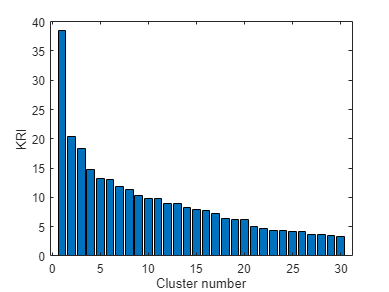

[numc,txt,raw]=xlsread('C:\Users\UPC\Desktop\hfcr.xlsx') ; %Input Data
gg = kmrgcdemo(numc,11);

li = zeros(length(numc),1);
for i = 1:length(gg)
    li(cell2mat(gg(i))) = i;
end

### MRGC clusters its own actual logging curve data

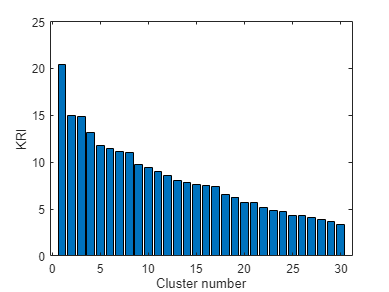

[numc,txt,raw]=xlsread('C:\Users\UPC\Desktop\hfcr.xlsx') ; % Input Data
num = normalize(numc);
gg = mrgcdemo(numc,8);

li = zeros(length(numc),1);
for i = 1:length(gg)
    li(cell2mat(gg(i))) = i;
end

### Visualization

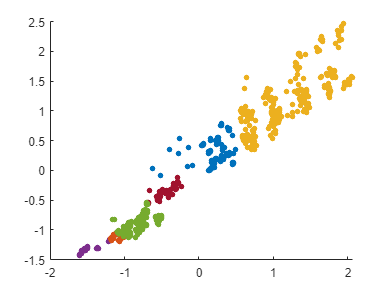

[m,n] = size(num);
data4 = zeros(m,1);
for i = 1:length(gg)
    data4(cell2mat(gg(1,i))) = i;
end
figure;
scatter(num(:,1),num(:,2),20,data4,'filled');
colormap("lines");

### k-means clusters its own actual logging curve data

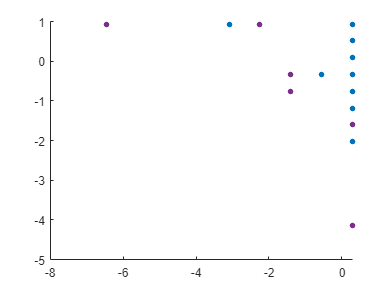

[idx1,C] = kmeans(num,8); 
%-------------------------------------------------------------------------
figure;
scatter(num(:,1),num(:,2),20,idx1,'filled');
colormap("lines");